% --- Setup ---
clear
sympref('AbbreviateOutput', false);

syms k l h w E nu x y alpha w0 I real
assume([k l h w E nu alpha w0],'real');
assumeAlso([l h E] > 0);
assumeAlso(-1 < nu & nu < 1/2);

% === Full stress field ============================
% Airy stress function with exponential-in-x ansatz
syms A B C D real
f   = (A + B*y)*cos(alpha*y) + (C + D*y)*sin(alpha*y);
phi = f*exp(alpha*x);

% Stresses from Airy
sigma_x = simplify(diff(phi, y, 2));
sigma_y = simplify(diff(phi, x, 2));      % = alpha^2*exp(alpha*x)*f(y)
tau_xy  = simplify(-diff(diff(phi, x), y)); % = -alpha*exp(alpha*x)*f'(y)

% --- Boundary conditions ---
% sigma_y(x,-h) = w*exp(alpha*x), sigma_y(x,h) = 0, tau_xy(x,±h)=0
% These reduce to: f(-h)=w/alpha^2, f(h)=0, f'(±h)=0
eqs = [
  subs(f, y, -h) == w/alpha^2, ...
  subs(f, y,  h) == 0, ...
  subs(diff(f,y), y,  h) == 0, ...
  subs(diff(f,y), y, -h) == 0];

S = solve(eqs, [A, B, C, D], 'ReturnConditions', false);

A_sol = simplify(S.A);
B_sol = simplify(S.B);
C_sol = simplify(S.C);
D_sol = simplify(S.D);

% --- Substitute back ---
phi     = simplify(subs(phi,     [A B C D], [A_sol B_sol C_sol D_sol]));
sigma_x = subs(sigma_x, [A B C D], [A_sol B_sol C_sol D_sol]);
sigma_y = simplify(subs(sigma_y, [A B C D], [A_sol B_sol C_sol D_sol]));
tau_xy  = subs(tau_xy,  [A B C D], [A_sol B_sol C_sol D_sol]);

% --- Quick verification of BCs (all should reduce to 0) ---
bc1 = simplify(subs(sigma_y, y, -h) - w*exp(alpha*x));
bc2 = simplify(subs(sigma_y, y,  h));
bc3 = simplify(subs(tau_xy,  y,  h));
bc4 = simplify(subs(tau_xy,  y, -h));


% === Reduced Deformation field ============================
syms C1 C2 C3
u =  w0*x*( 10*h^3*nu - 3*h^2*(5*nu + 2)*y - 5*y*( 3*l^2 - 3*l*x + x^2 - (nu+2)*y^2 ) ) ...
     /(20*E*h^3) ...
   - l*(nu + 2)*w0*y^3/(4*E*h^3) ...
   + C1*y + C2;

% v ≡ u_y(x,y)
v =  w0*( -40*h^3*y ...
        + 6*h^2*( 20*l*(nu+1)*x - (5*nu+8)*x^2 + (2*nu+5)*y^2 ) ...
        + 5*( 6*l^2*(x^2 + nu*y^2) ...
             - 4*l*( x^3 + 3*nu*x*y^2 ) ...
             + x^4 + 6*nu*x^2*y^2 - (2*nu+1)*y^4 ) ) ...
     /(80*E*h^3) ...
   + C1*x + C3;

eqs = [ ...
    subs(u, {x,y}, {l,0}) == 0, ...                           % u(0,0)=0
    subs(v, {x,y}, {l,0}) == 0, ...                           % v(0,0)=0
    subs(diff(v,x), {x,y}, {l,0}) == 0 ...        % (v_x - u_y)(0,0)=0
];

S = solve(eqs, [C1, C2, C3]);   % solve only for the rigid-body constants
u = simplify(subs(u, [C1 C2 C3], [S.C1 S.C2 S.C3]))

$$u = \frac{w_{0}\,x\,\left(10\,\nu \,h^{3}-3\,y\,\left(5\,\nu +2\right)\,h^{2}+5\,y\,\left(-3\,l^{2}+3\,l\,x-x^{2}+\left(\nu +2\right)\,y^{2}\right)\right)}{20\,\text{E}\,h^{3}}-\frac{l\,\nu \,w_{0}}{2\,\text{E}}-\frac{w_{0}\,y\,\left(6\,h^{2}\,l+5\,l^{3}+15\,h^{2}\,l\,\nu \right)}{20\,\text{E}\,h^{3}}-\frac{l\,w_{0}\,y^{3}\,\left(\nu +2\right)}{4\,\text{E}\,h^{3}}$$

v = subs(v, [C1 C2 C3], [S.C1 S.C2 S.C3])

$$v = \frac{w_{0}\,\left(30\,l^{2}\,\left(x^{2}+\nu \,y^{2}\right)-20\,l\,\left(x^{3}+3\,\nu \,x\,y^{2}\right)+6\,h^{2}\,\left(\left(-5\,\nu -8\right)\,x^{2}+20\,l\,\left(\nu +1\right)\,x+\left(2\,\nu +5\right)\,y^{2}\right)-5\,y^{4}\,\left(2\,\nu +1\right)-40\,h^{3}\,y+5\,x^{4}+30\,\nu \,x^{2}\,y^{2}\right)}{80\,\text{E}\,h^{3}}-\frac{48\,h^{2}\,l^{2}\,w_{0}-5\,l^{4}\,w_{0}+30\,h^{2}\,l^{2}\,\nu \,w_{0}}{80\,\text{E}\,h^{3}}-\frac{w_{0}\,x\,\left(6\,h^{2}\,l+5\,l^{3}+15\,h^{2}\,l\,\nu \right)}{20\,\text{E}\,h^{3}}$$


v0_w0 = simplify(subs(v,y,0))

$$v0\_w0 = -\frac{w_{0}\,{\left(l-x\right)}^{2}\,\left(10\,l\,x+30\,h^{2}\,\nu +48\,h^{2}-5\,l^{2}-5\,x^{2}\right)}{80\,\text{E}\,h^{3}}$$

u0_w0 = simplify(subs(u,y,0))

$$u0\_w0 = -\frac{\nu \,w_{0}\,\left(l-x\right)}{2\,\text{E}}$$



syms P
I = 2/3*h^3;
v0_P = P/6*E*I*(-x^3+3*l^2*x-2*l^3);
u0_P = 0;

P_star = simplify(solve(subs(v0_w0+v0_P,x,0)==0,P,'ReturnConditions',false))

$$P\_star = -\frac{9\,w_{0}\,\left(30\,h^{2}\,\nu +48\,h^{2}-5\,l^{2}\right)}{160\,{\text{E}}^{2}\,h^{6}\,l}$$


v0 = simplify(subs(v0_P,P,P_star) + v0_w0)

$$v0 = \frac{w_{0}\,x\,{\left(l-x\right)}^{2}\,\left(10\,l\,x+30\,h^{2}\,\nu +48\,h^{2}-25\,l^{2}\right)}{160\,\text{E}\,h^{3}\,l}$$


v0 = subs(v0,[w0,l,h,nu,E],[1,10,1,0.2,500]);

$$v0 = \frac{x\,\left(100\,x-2446\right)\,{\left(x-10\right)}^{2}}{800000}$$

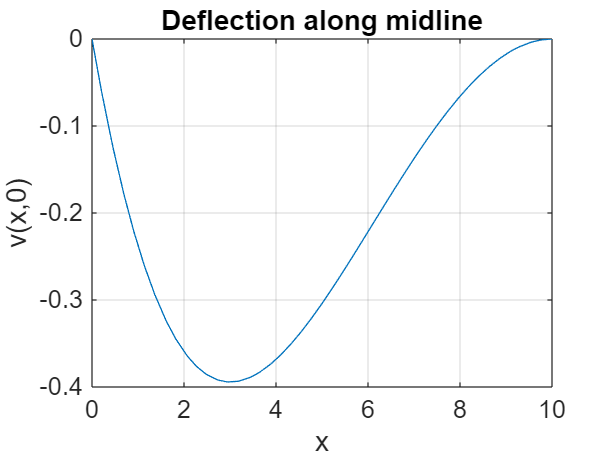


v_fun = matlabFunction(v0, 'Vars', x);
fplot(v_fun, [0, 10]); grid on
xlabel('x'); ylabel('v(x,0)');
title('Deflection along midline');